# Analysis of TBX2 and TBX3 in Pancreatic Cancer

## Background

TBX2 and TBX3 are transcription factors that play crucial roles in cancer progression, including pancreatic cancer. These genes regulate cell cycle pathways, and their dysregulation can lead to tumor development. In this assignment, we analyse differentially expressed genes associated with TBX2 and TBX3 in pancreatic cancer and perform enrichment analysis using Enrichr followed by network analysis.

### Objective 

- Load and analyse differentially expressed genes from an Excel file.

- Perform enrichment analysis using Enrichr.

- Visualize gene overlaps using Venn diagrams.

- Create networks of enriched pathways.

### To Be Graded

- Convert this MATLAB script to Python and submit the Python code. Use Pandas, Matplotlib, and Seaborn.

- Provide a comprehensive report that includes the results, figures, and an interpretation of the findings in a biological context.

### Step 1: Load the Data

The data is stored in an Excel file containing differentially expressed genes between tumour vs. normal pancreatic samples.


% start on a clean slate 
clc; clear; close all;

% change the directory
cd('C:\Users\LENOVO\Documents\MATLAB\TB3 Pancreatic cancer Analysis\AssignmentFiles')

## Venn Diagram of Regulated Genes

We analyse the overlap between TBX2 and TBX3 differentially expressed genes in pancreatic cancer. Venn diagrams help visualize the shared and unique genes.


 Running the analysis for High Tumors 


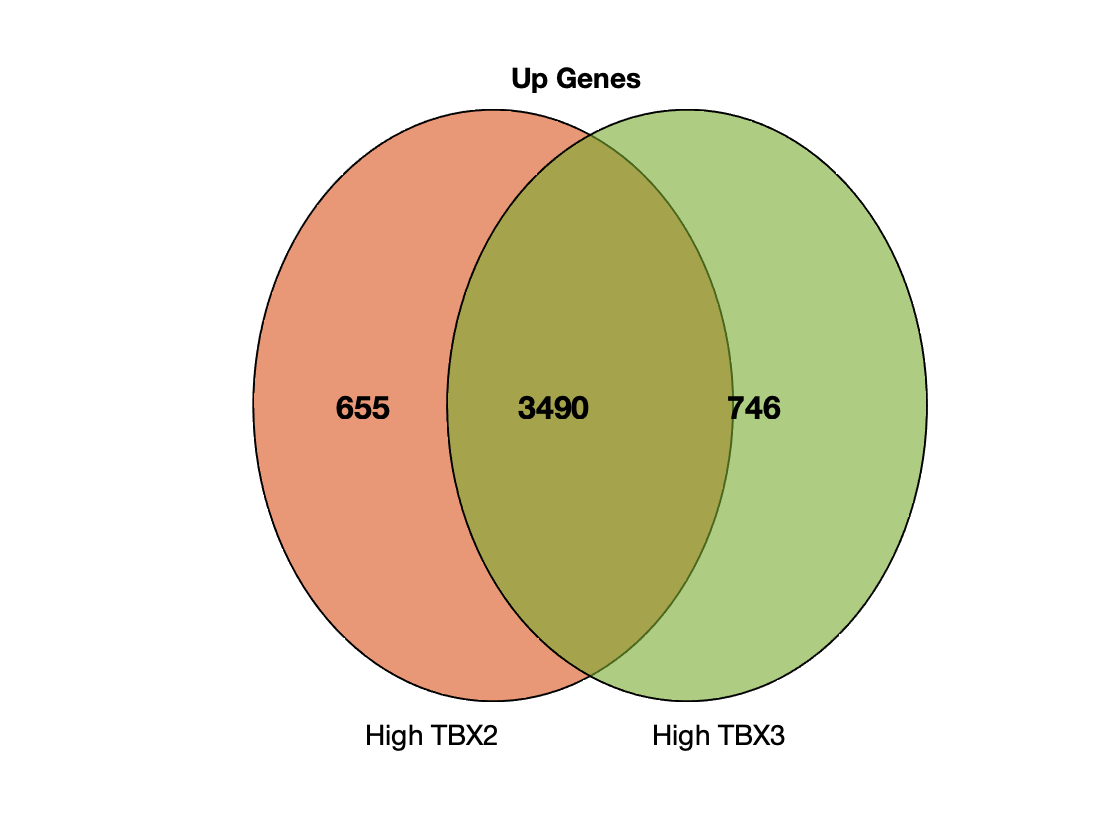

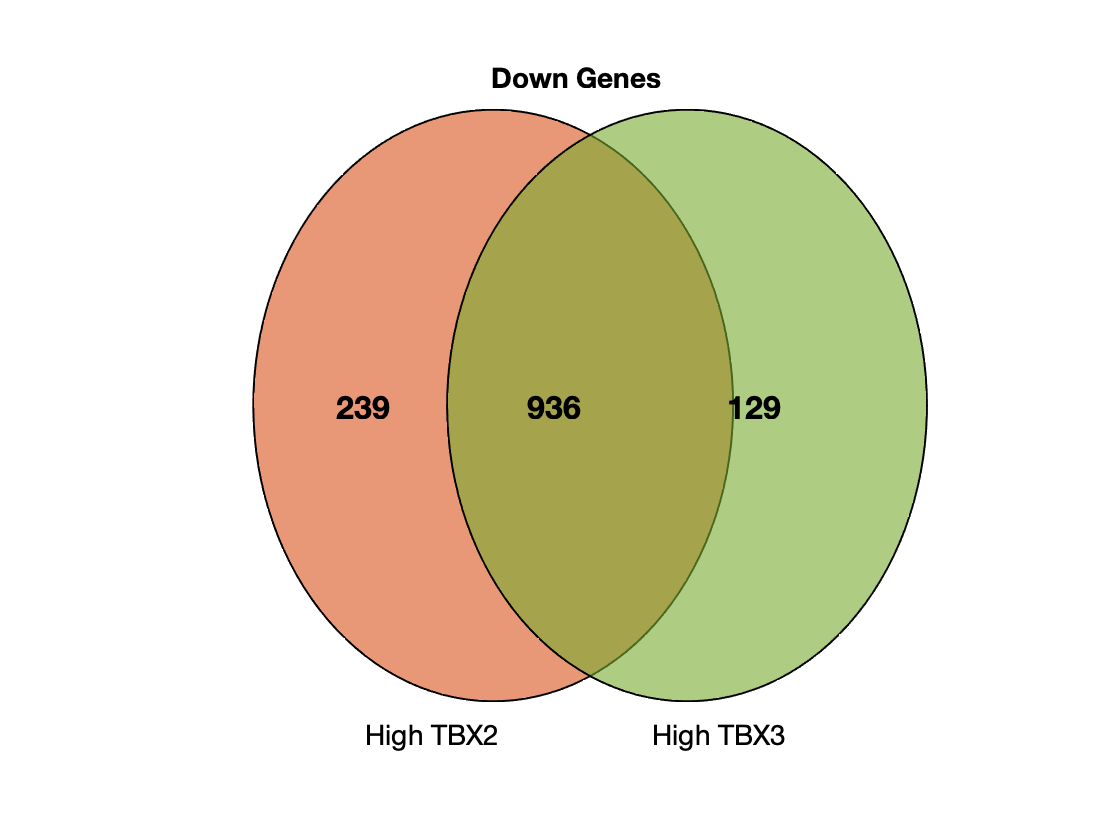


 Running the analysis for Low Tumors 


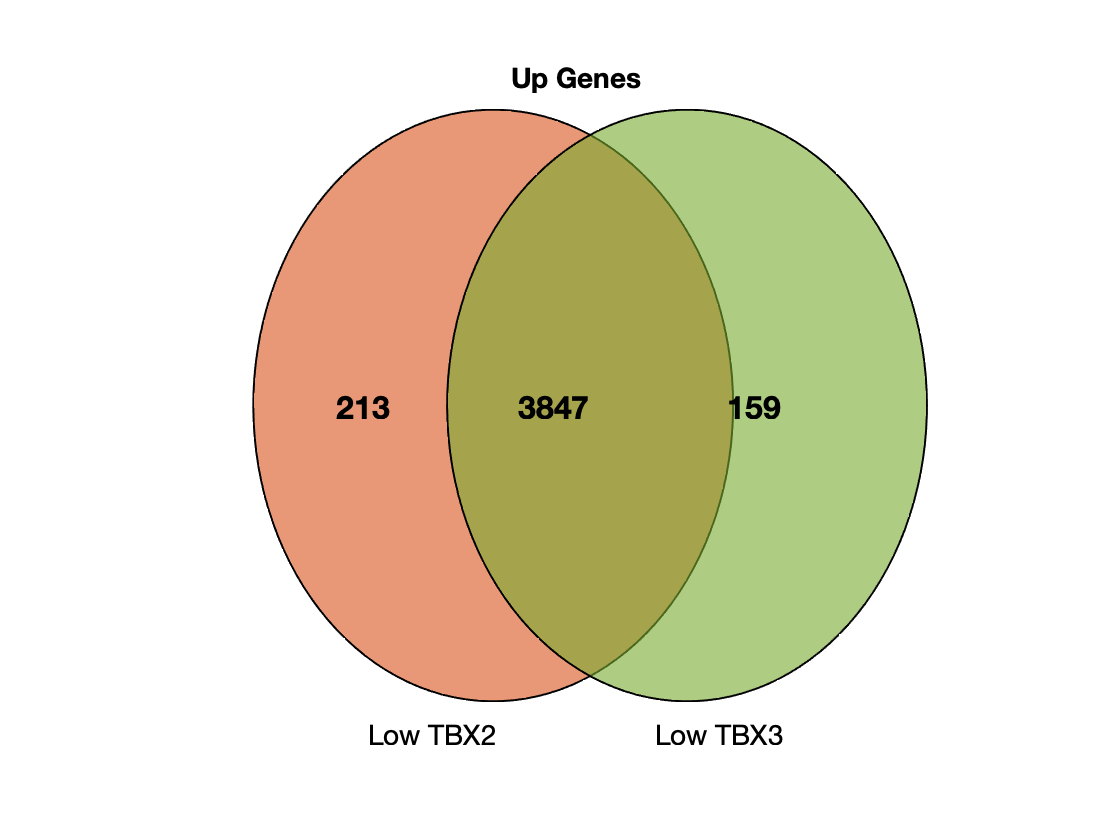

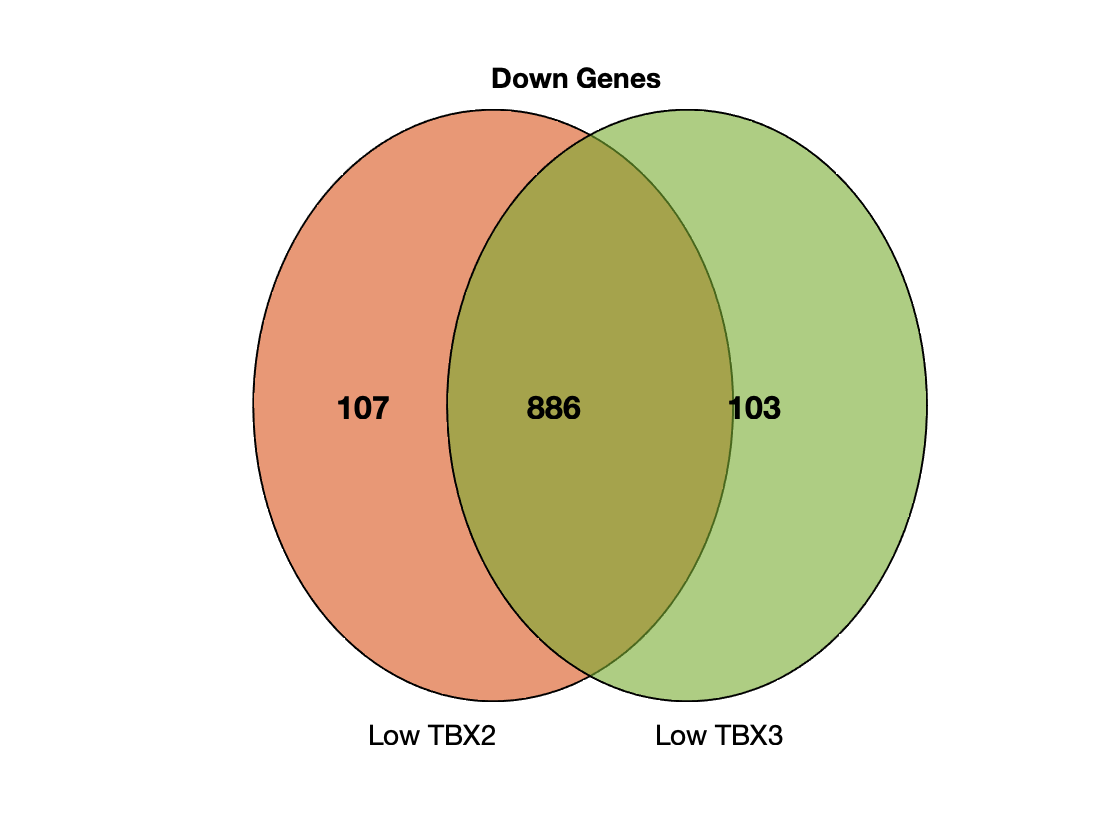

% Define the gene regulation groups:
% 'Up Genes ' indicates genes that are upregulated, and 'Down Genes ' for
% downregulated genes.
regGroups = {'Up Genes ', 'Down Genes '};

% Define the tumor groups: 
% "High" and "Low" refer to the expression levels of the tumour groups.
tumourGroups = ["High", "Low"];

% Loop through each tumour group (High and Low)
for kk = 1:length(tumourGroups)
    
    % Display current tumor group analysis progress in the console.
    fprintf('\n Running the analysis for %s Tumors \n', tumourGroups{kk})

    % Nested loop: iterate over each regulation group (Up Genes and Down
    % Genes)
    for ii = 1:length(regGroups)
        
        % --------------------- Load the Data --------------------- Read
        % the differentially expressed genes for TBX2 from the Excel file.
        % The sheet name is constructed by combining the regulation group,
        % tumor group, and ' TBX2'.
        curTBX2 = readtable( ...
            'Diffentially Expressed Genes Tumour vs Normal.xlsx', ...
            'Sheet', [regGroups{ii}, tumourGroups{kk}, ' TBX2']);
        
        % Read the differentially expressed genes for TBX3 from the Excel
        % file. The sheet name is constructed similarly to the TBX2 sheet.
        curTBX3 = readtable( ...
            'Diffentially Expressed Genes Tumour vs Normal.xlsx', ...
            'Sheet', [regGroups{ii}, tumourGroups{kk}, ' TBX3']);

        % --------------------- Find Overlapping Genes --------------------- 
        % Identify the common genes between TBX2 and TBX3 by intersecting the 
        % 'HugoSymbol' columns.
        commonGenes = intersect(curTBX2.HugoSymbol, curTBX3.HugoSymbol);

        % --------------------- Plotting the Venn Diagram --------------------- 
        % Create a new figure for the Venn diagram.
        figure();
        
        % Draw a basic Venn diagram using dummy circle sizes (200, 200) and
        % a specified overlap. 'venn' function is used for illustration,
        % and 'EdgeColor' sets the border color of circles.
        venn_plot([150, 150], 75, 'EdgeColor', 'black')
        hold on  % Retain current plot for adding text annotations

        % --------------- Calculate Values for Plot Annotation -------------- 
        % Calculate the number of genes unique to TBX2 by subtracting the number
        % of common genes from the total number of genes in curTBX2.
        myNumText(1) = height(curTBX2) - length(commonGenes);
        
        % Number of genes that are common to both TBX2 and TBX3.
        myNumText(2) = length(commonGenes);
        
        % Calculate the number of genes unique to TBX3.
        myNumText(3) = height(curTBX3) - length(commonGenes);

        % --------------------- Annotate the Venn Diagram --------------------- 
        % positions (normalized) along the horizontal axis for placing the numbers.
        textPos = [0.25, 0.47, 0.70];
        
        % Loop over each position to add the calculated numbers onto the
        % Venn diagram.
        for jj = 1:length(textPos)
            text(textPos(jj), 0.5, num2str(myNumText(jj)), ...
                'Units', 'normalized', 'FontWeight', 'bold', ...
                'FontSize', 16, 'HorizontalAlignment', 'center')
        end

        % Add the regulation group label (e.g., "Up Genes" or "Down Genes")
        % to the top of the Venn diagram.
        text(0.5, 0.98, [regGroups{ii}], 'Units', 'normalized', ...
            'FontWeight', 'bold', 'FontSize', 14, 'HorizontalAlignment', 'center')

        % Define positions for labeling the individual gene groups at the
        % bottom of the Venn diagram.
        textPos = [0.33, 0.66];
        myGroups = {'TBX2', 'TBX3'};  % Names for the two groups
        for jj = 1:length(textPos)
            % Label the bottom of the diagram with the tumor group and gene
            % name (e.g., "High TBX2").
            text(textPos(jj), 0.02, [tumourGroups{kk}, ' ', myGroups{jj}], ...
                'Units', 'normalized', 'FontWeight', 'normal', ...
                'FontSize', 14, 'HorizontalAlignment', 'center')
        end

        hold off  % Release the plot hold for next iterations
    end 
end

## Gene Set Enrichment Analysis Using Enrichr

Enrichr is an online tool used for gene set enrichment analysis. In this section, we analyze significantly differentially expressed genes for TBX2 and TBX3 to identify enriched biological pathways. The analysis is performed using multiple  gene set libraries, and the results are visualized and saved for further interpretation.

### IMPORTANT PREPARATION:

Before running this analysis, you must create two text files:

1. A text file for the upregulated genes in "TBX2 High vs Normal Pancreas" tissue.

2. A text file for the upregulated genes in "TBX3 High vs Normal Pancreas" tissue.

The file names of the Enrichr results should be formatted to match the expected naming convention:

For example, if using the "GO_Molecular_Function_2021_table.txt" as the enrichment file, the full file names should be:

- 'High TBX2 GO_Molecular_Function_2021_table.txt'

- 'High TBX3 GO_Molecular_Function_2021_table.txt'

This naming format is necessary because the code below constructs the file name by prepending 'High TBX2 ' or 'High TBX3 ' to the base file name (provided in enrichrVars). Ensuring the file names match will allow the MATLAB (and corresponding Python) script to correctly load the Enrichr enrichment data.


Running analysis for GO Molecular Function Enrichments


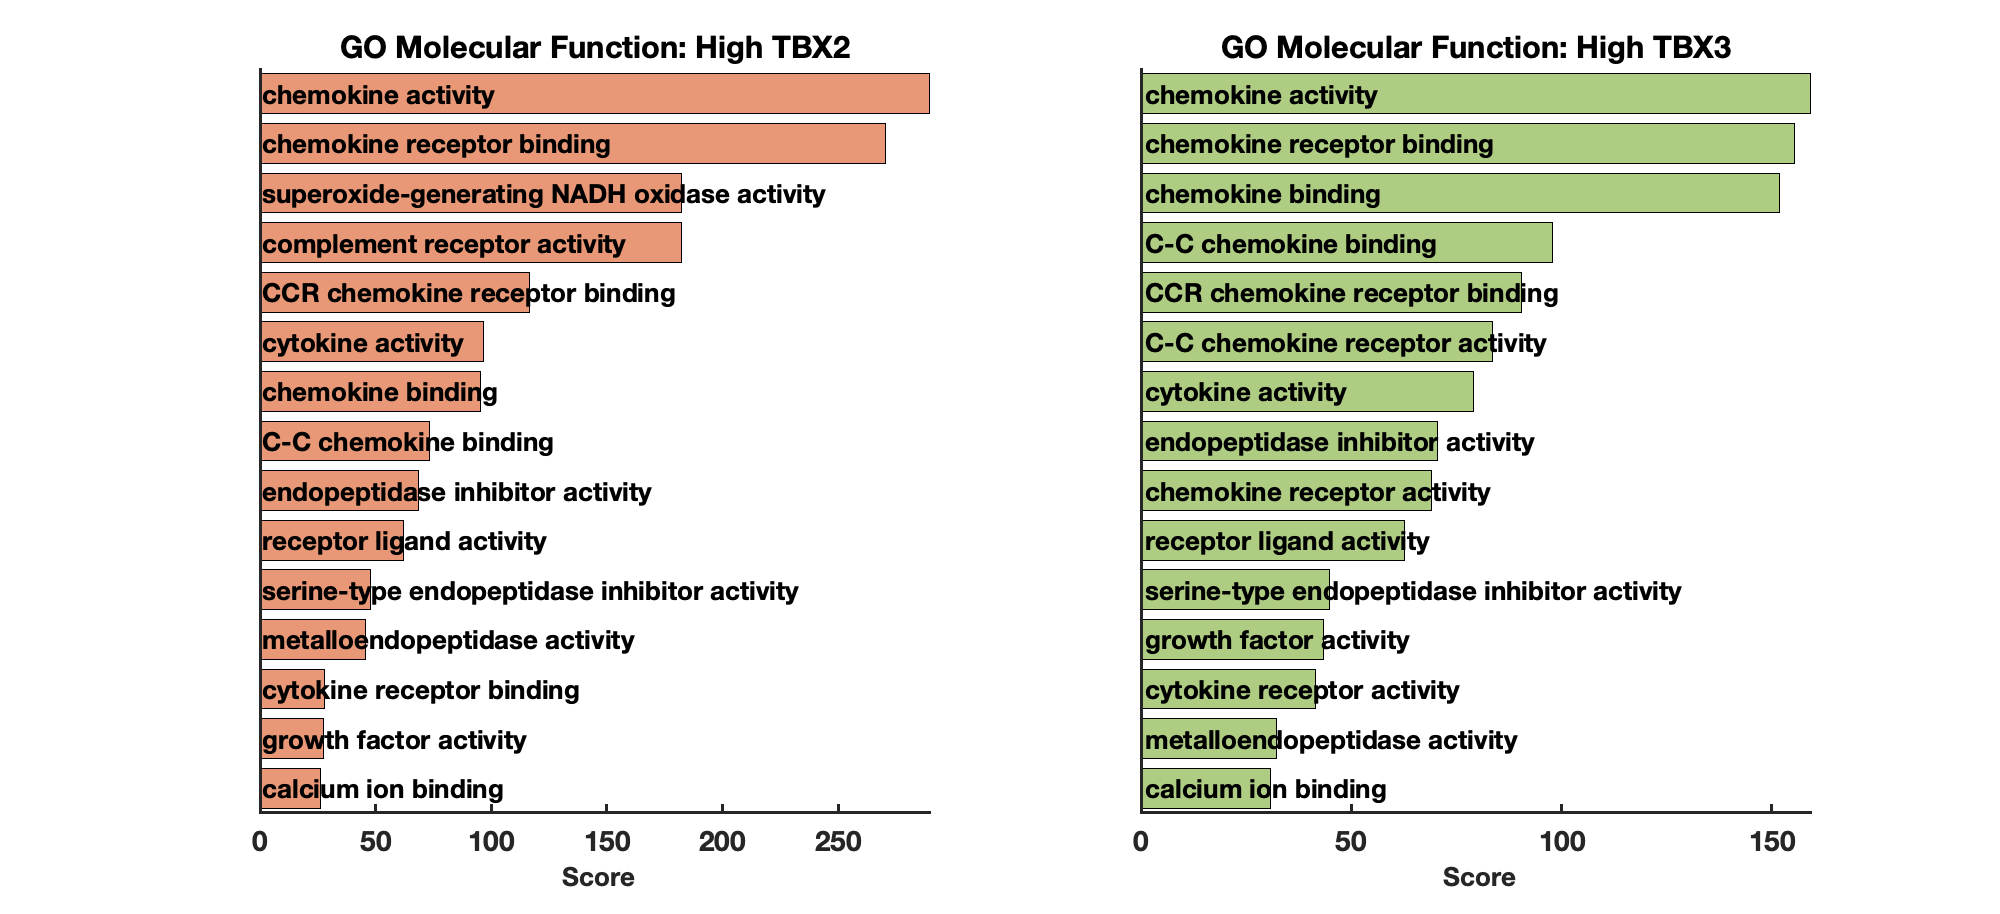

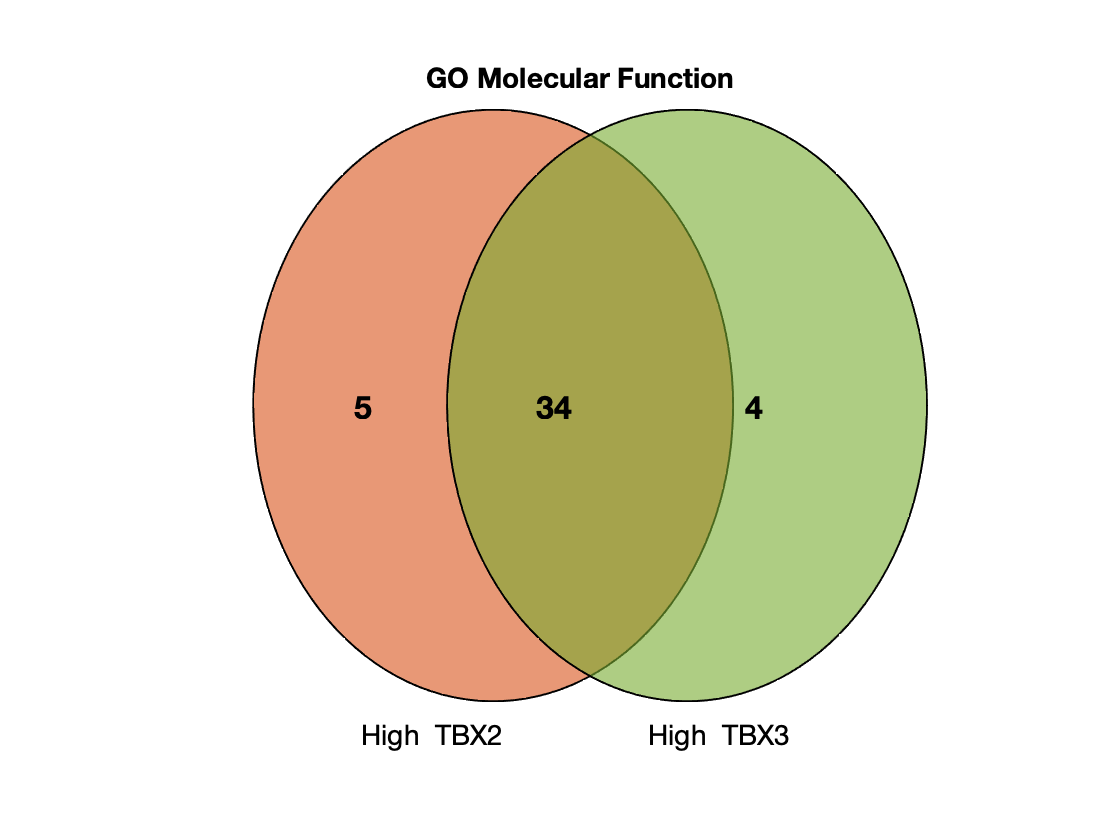


Running analysis for Reactome Enrichments


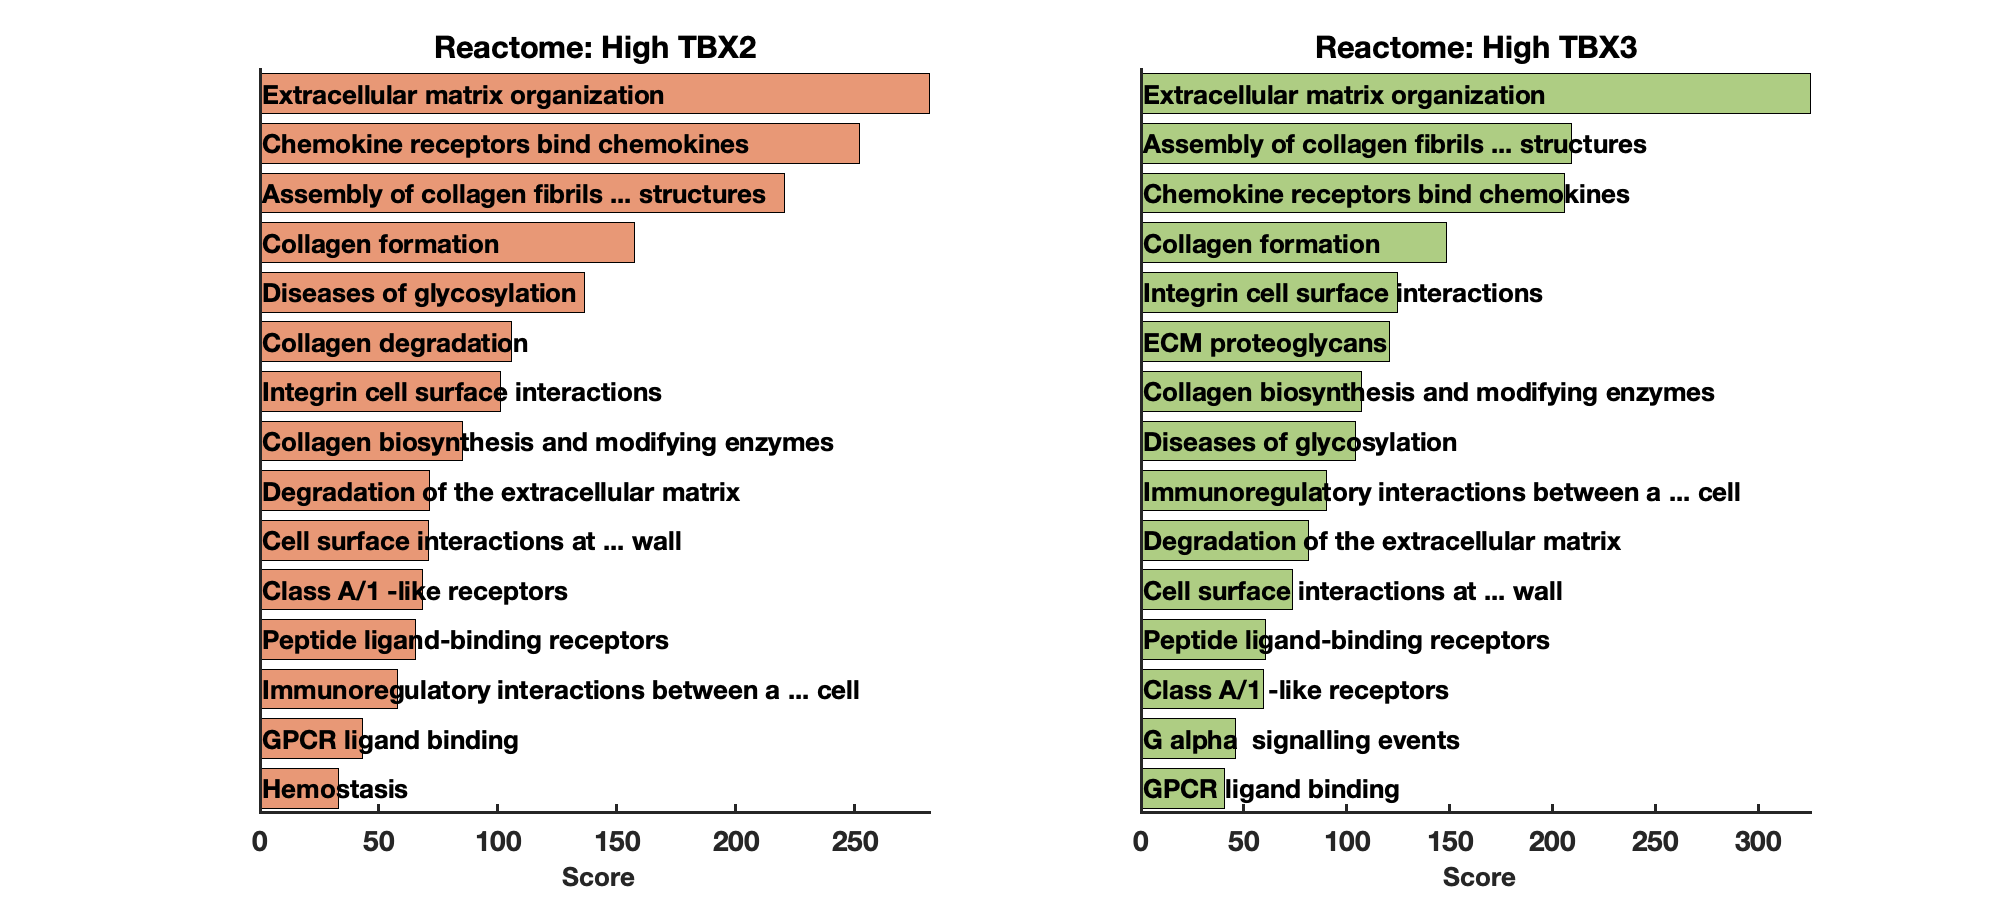

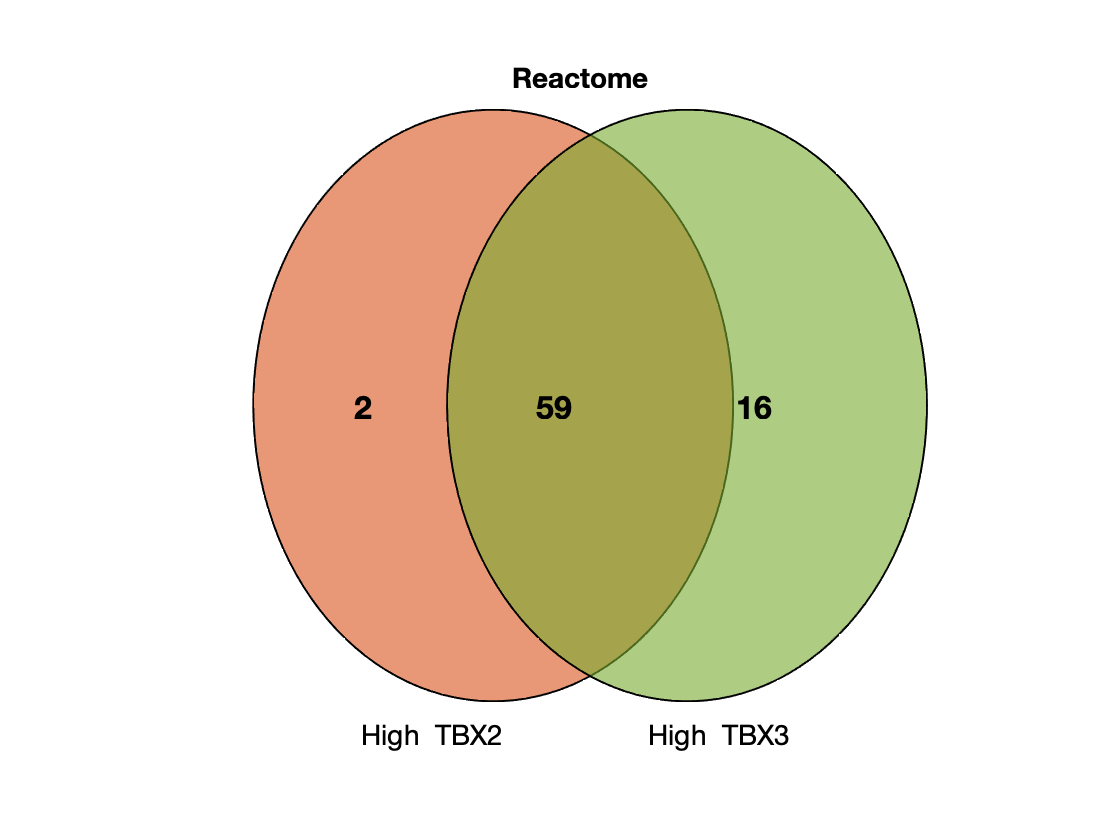


Running analysis for MSigDB Hallmark Enrichments


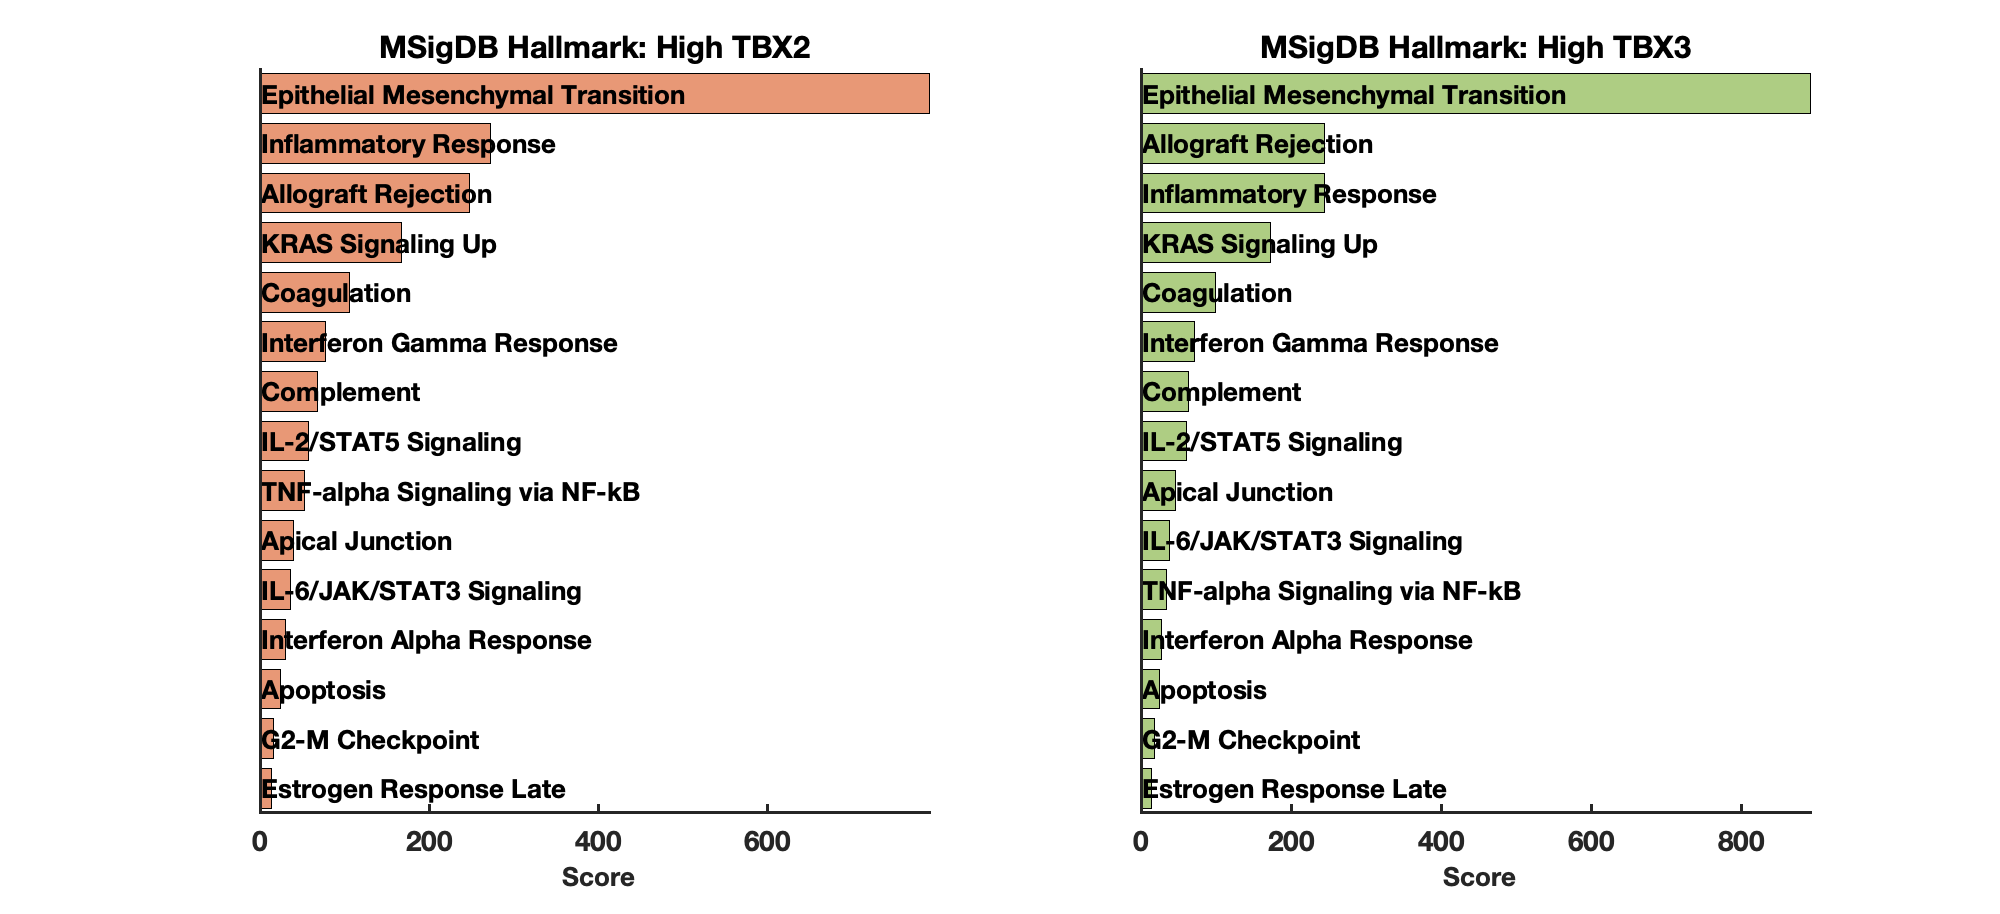

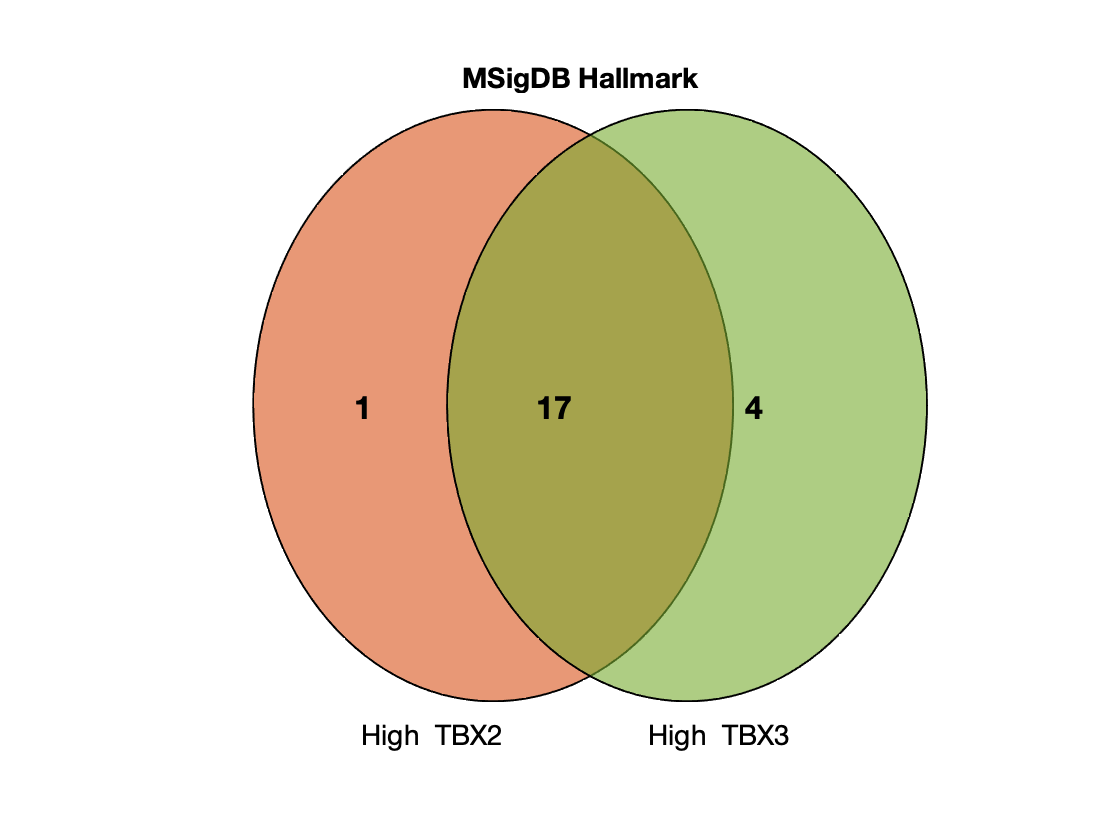


Running analysis for GO Biological Process Enrichments


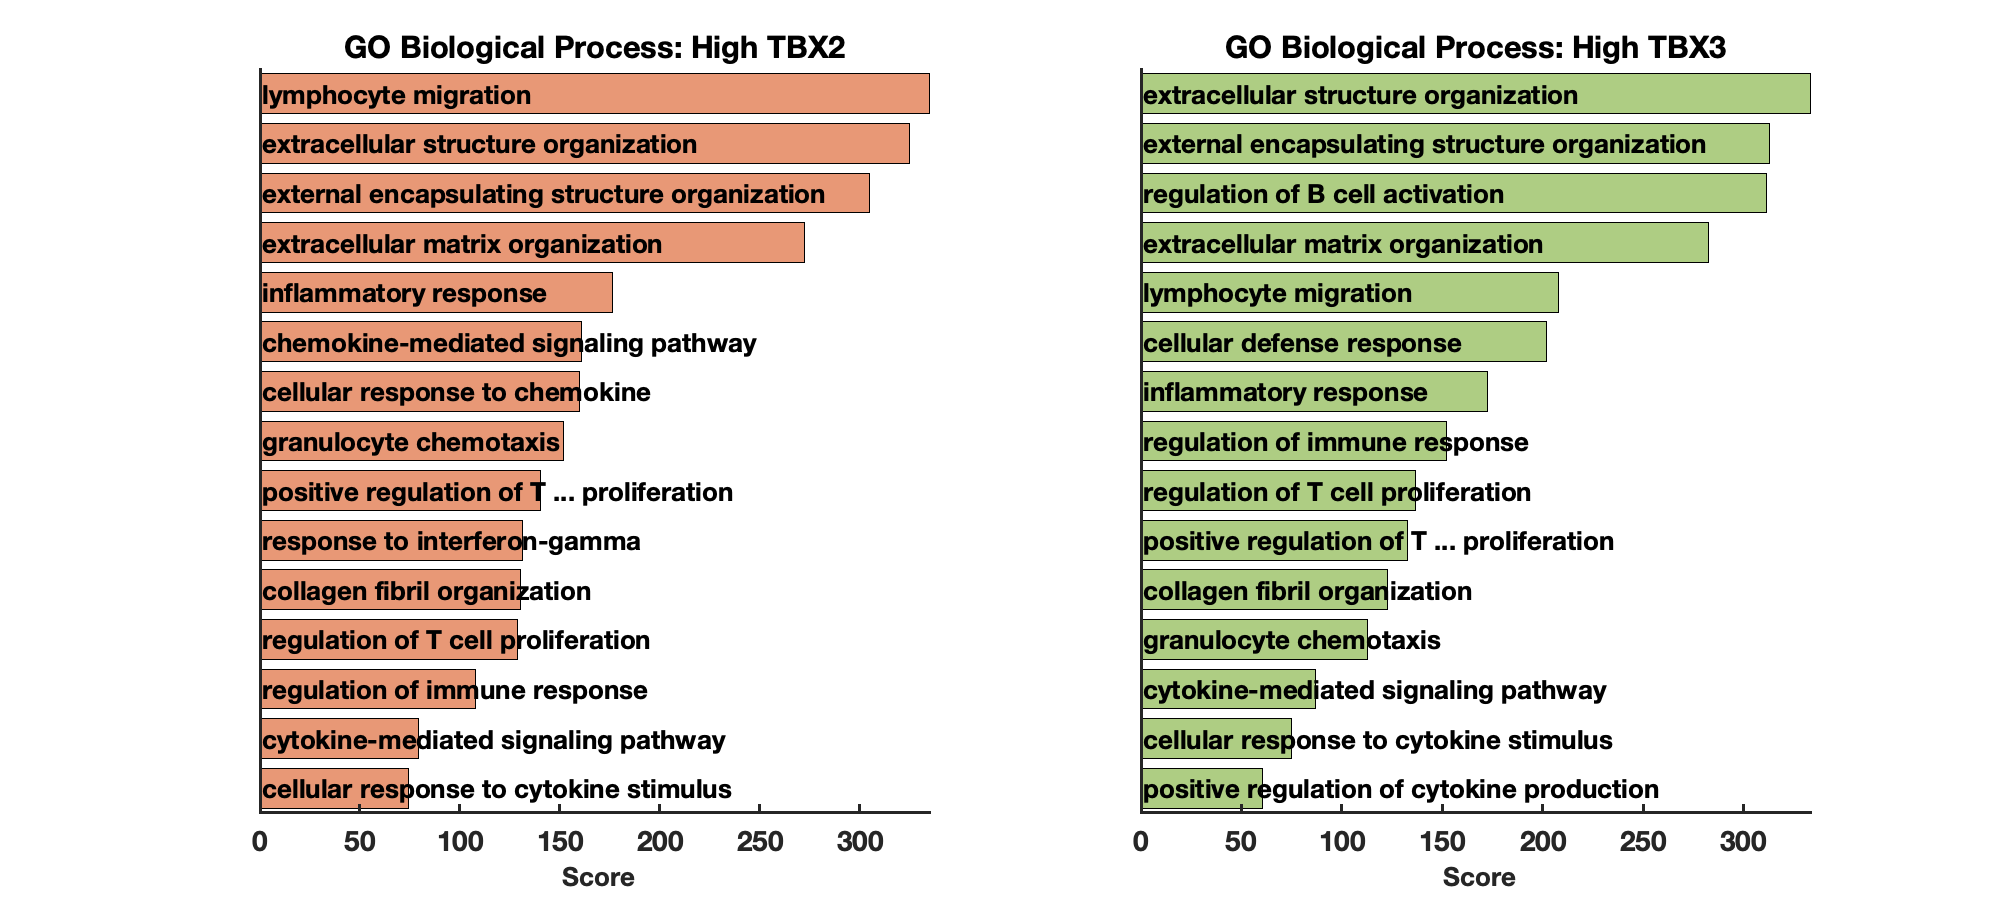

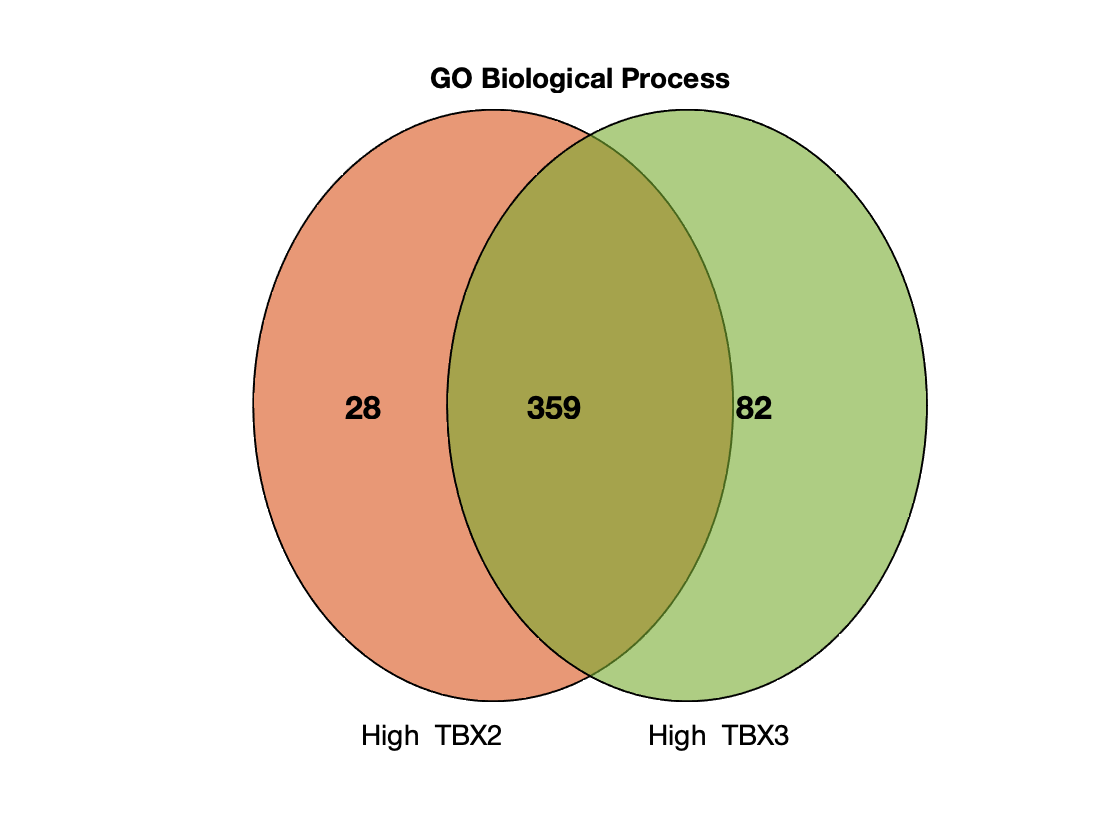

% Define the file names for the enrichment analysis tables corresponding to different gene sets.
enrichrVars = {'GO_Molecular_Function_2021_table.txt', 'Reactome_2016_table.txt', ...
    'MSigDB_Hallmark_2020_table.txt', 'GO_Biological_Process_2021_table.txt'};

% Define human-readable names for the plots corresponding to each enrichment analysis.
plotNames = {'GO Molecular Function', 'Reactome', 'MSigDB Hallmark', 'GO Biological Process'};

% Loop over each enrichment variable/library to perform analysis for each gene set.
for ii = 1:length(enrichrVars)
    
    % Display current analysis progress in the console.
    fprintf('\nRunning analysis for %s Enrichments\n', plotNames{ii})
    
    % ---------------------------
    % Data Loading
    % ---------------------------
    % Load the enrichment results for TBX2.
    % The sheet name is constructed as 'High TBX2 ' concatenated with the current file name,
    % e.g., 'High TBX2 GO_Molecular_Function_2021_table.txt'
    enrichTBX2 = readtable(['High TBX2 ', enrichrVars{ii}], 'Format', 'auto'); 
    
    % Similarly, load the enrichment results for TBX3.
    % The sheet name is constructed as 'High TBX3 ' concatenated with the current file name.
    enrichTBX3 = readtable(['High TBX3 ', enrichrVars{ii}], 'Format', 'auto');
    
    % ---------------------------
    % Data Cleaning
    % ---------------------------
    % Remove unwanted characters and extra text from the enriched term names.
    % The regex patterns are used to remove characters such as parentheses, colons,
    % specific identifiers (e.g., 'Homo sapiens'), and other non-informative text.
    enrichTBX2.Term = strtrim(regexprep(enrichTBX2.Term, ...
        {'\(+\w*', '\:+\w*', '\)', '\R-HSA-+\w*', 'Homo sapiens', '\w* raw'}, ''));
    enrichTBX3.Term = strtrim(regexprep(enrichTBX3.Term, ...
        {'\(+\w*', '\:+\w*', '\)', '\R-HSA-+\w*', 'Homo sapiens', '\w* raw'}, ''));
    
    % ---------------------------
    % Visualization of Enrichment Results
    % ---------------------------
    % Define colors for the gene groups to be used in the plots. Each row corresponds 
    % to one gene group (TBX2 and TBX3).
    groupColors = [0.85, 0.33, 0.10; 0.47, 0.67, 0.19];
    
    % Call a custom plotting function to visualize the enrichment results for TBX2 and TBX3.
    % The function 'enrichr_data_plotter' to generate relevant plots based on the data.
    enrichr_data_plotter2(enrichTBX2, enrichTBX3, plotNames{ii}, groupColors, ...
        {'High TBX2', 'High TBX3'});
    
    % ---------------------------
    % Saving the Enrichment Results
    % ---------------------------
    % Write the enrichment results to an Excel file for further analysis or reporting.
    % Each result is saved on a separate sheet named after the enrichment type and gene.
    writetable(enrichTBX2, 'Enrichment Results.xlsx', 'Sheet', [plotNames{ii}, '-TBX2'])
    writetable(enrichTBX3, 'Enrichment Results.xlsx', 'Sheet', [plotNames{ii}, '-TBX3'])
    
    % ---------------------------
    % Filtering Significant Pathways
    % ---------------------------
    % Filter the enrichment results to include only the pathways with an Adjusted p-value 
    % less than 0.05, indicating statistical significance.
    enrichTBX2 = enrichTBX2(enrichTBX2.AdjustedP_value < 0.05, :);
    enrichTBX3 = enrichTBX3(enrichTBX3.AdjustedP_value < 0.05, :);
    
    % Identify common enriched pathways between TBX2 and TBX3 by finding the intersection
    % of their 'Term' fields.
    commonPathways = intersect(enrichTBX2.Term, enrichTBX3.Term);
    
    % ---------------------------
    % Plotting the Venn Diagram of Enriched Pathways
    % ---------------------------
    % Create a new figure to visualize the overlap of significantly enriched pathways.
    figure();
    
    % Draw a Venn diagram using dummy circle sizes (150 for each group) and a specified overlap.
    % The 'EdgeColor' parameter sets the border color of the circles.
    venn_plot([150, 150], 75, 'EdgeColor', 'black');
    hold on  % Retain the current plot to add annotations
    
    % Calculate the numbers to annotate:
    % 1. Unique pathways in TBX2: Total significant TBX2 pathways minus the common pathways.
    % 2. Common pathways: Count of common enriched pathways.
    % 3. Unique pathways in TBX3: Total significant TBX3 pathways minus the common pathways.
    myNumText(1) = height(enrichTBX2) - length(commonPathways);
    myNumText(2) = length(commonPathways);
    myNumText(3) = height(enrichTBX3) - length(commonPathways);
    
    % Define horizontal positions (normalized) for placing the text annotations.
    textPos = [0.25, 0.47, 0.70];
    
    % Loop through the positions and add the calculated text annotations to the Venn diagram.
    for jj = 1:length(textPos)
        text(textPos(jj), 0.5, num2str(myNumText(jj)), ...
            'Units', 'normalized', 'FontWeight', 'bold', ...
            'FontSize', 16, 'HorizontalAlignment', 'center')
    end
    
    % Add the plot title (enrichment library name) at the top of the Venn diagram.
    text(0.5, 0.98, [plotNames{ii}], 'Units', 'normalized', ...
        'FontWeight', 'bold', 'FontSize', 14, 'HorizontalAlignment', 'center')
    
    % Define positions and labels for the bottom of the Venn diagram.
    textPos = [0.33, 0.66];
    myGroups = {'TBX2', 'TBX3'};
    
    % Loop through each position to add group labels (e.g., "High TBX2" and "High TBX3").
    for jj = 1:length(textPos)
        text(textPos(jj), 0.02, ['High ', ' ', myGroups{jj}], ...
            'Units', 'normalized', 'FontWeight', 'normal', ...
            'FontSize', 14, 'HorizontalAlignment', 'center')
    end
    
    hold off  % Release the plot hold for subsequent figures
end

## Create a Network of Genes

In this section, we generate a network based on the significantly upregulated genes. The network will later be used for visualization in external tools such as Cytoscape or yEd.


 Reading the Human Interactome Data 


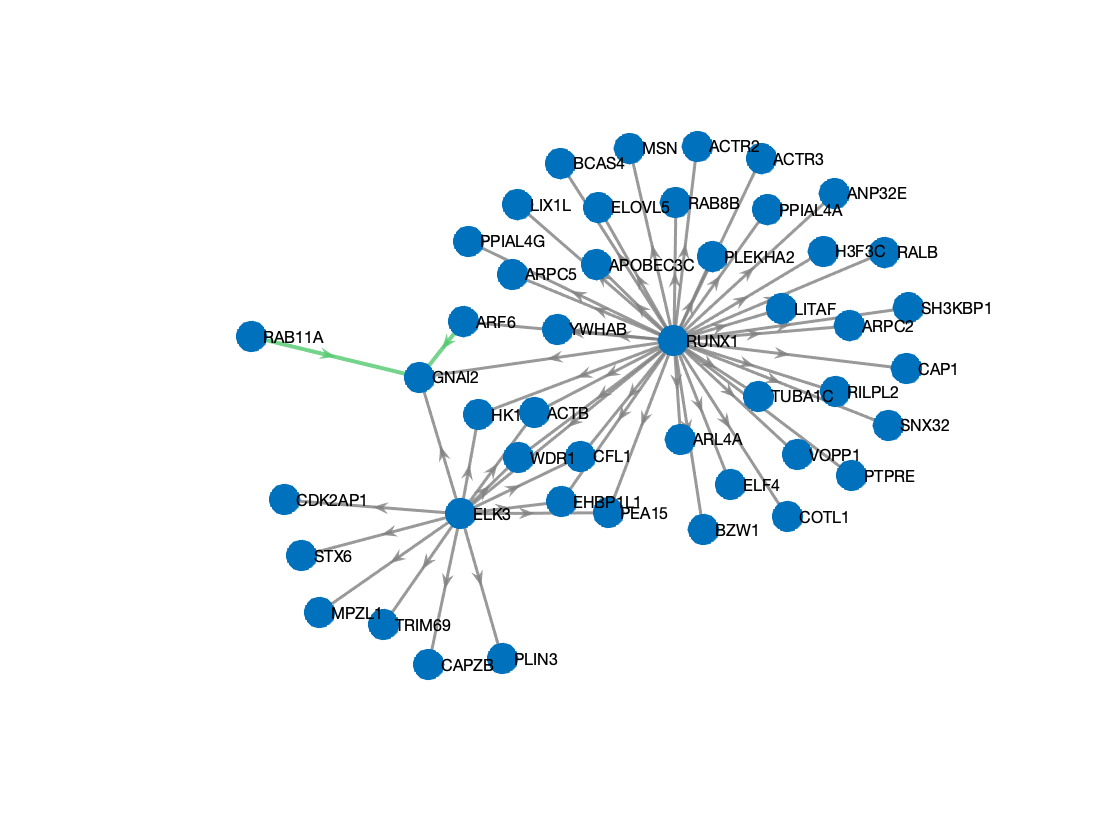

% -------------------------------------------------------------------------
% Step 1: Load the Upregulated Gene Data
% -------------------------------------------------------------------------
% Read the table containing the significantly upregulated genes for TBX3.
% The Excel file 'Diffentially Expressed Genes Tumour vs Normal.xlsx' has a sheet
% named 'Up Genes High TBX3' which stores these genes.
theUpGenes = readtable(...
    'Diffentially Expressed Genes Tumour vs Normal.xlsx',...
    'Sheet','Up Genes High TBX3');

% -------------------------------------------------------------------------
% Step 2: Extract Genes for Network Creation
% -------------------------------------------------------------------------
% For network construction, we select the top 100 genes based on their order in the table.
% The gene symbols are stored in the column named 'HugoSymbol'.
% Adjust the index if you wish to include a different number of genes.
myGenes = theUpGenes.HugoSymbol(1:100);

% -------------------------------------------------------------------------
% Step 3: Create the Network Data
% -------------------------------------------------------------------------
% Use a custom function 'createNetworkLocal' to build the network data.
% This function processes the list of genes and generates the network structure (nodes and edges)
% based on underlying interactions or biological relationships.
network = createNetworkLocal(myGenes);


% -------------------------------------------------------------------------
% Step 4: Export the Network Data
% -------------------------------------------------------------------------
% Write the network data to an Excel file, which can later be imported into network 
% visualization tools such as Cytoscape or yEd.
% The network is saved in a sheet named 'UpGenes TBX3' within the file 'yED_networks.xlsx'.
writetable(network, 'yED_networks.xlsx', 'Sheet', 'UpGenes TBX3');
